# [**Deep Learning**](https://apmonitor.com/pds/index.php/Main/MultilayerPerceptronNeuralNetwork)

## Introduction

A neural network regressor is a type of machine learning model that is used for regression tasks. It is a type of artificial neural network that is composed of multiple layers of interconnected artificial neurons (also known as nodes or units) that are trained to predict the value of a continuous dependent variable (the response variable) based on the values of one or more independent variables (the predictor variables).

A neural network regressor typically consists of an input layer, one or more hidden layers, and an output layer. The input layer receives the values of the predictor variables, and the output layer produces the predicted value of the response variable. The hidden layers process the input data and pass it through to the output layer.

The nodes in the hidden layers are typically equipped with an activation function, which is a non-linear function that transforms the input data. The activation function allows the neural network to model non-linear relationships between the predictor variables and the response variable.

The weights and biases of the connections between the nodes are learned from the training data using an optimization algorithm, such as stochastic gradient descent. The optimization algorithm adjusts the weights and biases to minimize the difference between the predicted values of the response variable and the observed values of the response variable in the training data.

Deep learning is a type of machine learning with a multi-layered neural network. It is one of many machine learning methods for synthesizing data into a predictive form.

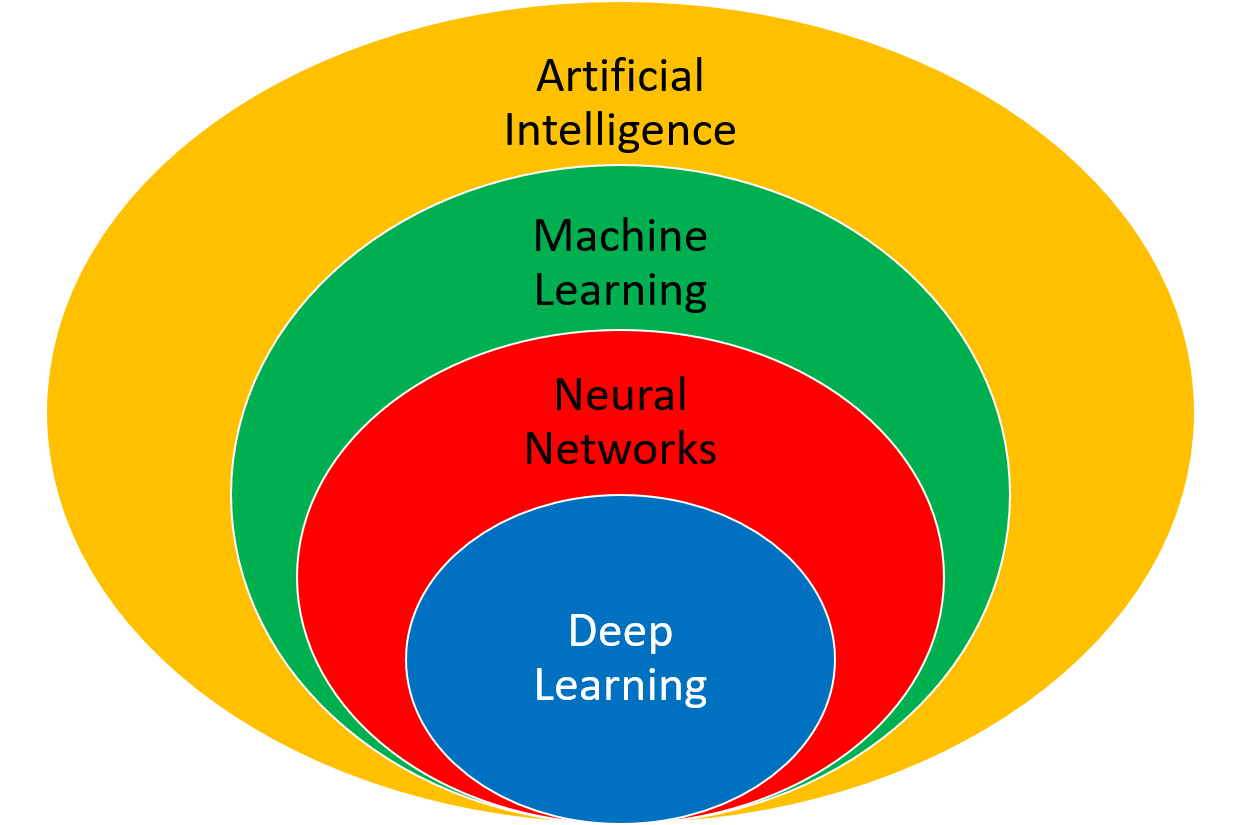

Two applications of deep learning are regression (predict outcome) and [classification (distinguish among discrete options)](https://apmonitor.com/pds/index.php/Main/DeepLearningNeuralNetwork). In each case, there is training data that is used to adjust weights (unknown parameters) that minimize a loss function (objective function).

A trained model predicts outcomes based on new input conditions that aren't in the original data set. Some of the typical steps for building and deploying a deep learning application are data consolidation, data cleansing, model building, training, validation, and deployment.

## Data Preparation

- Consolidation - consolidation is the process of combining disparate data (Excel spreadsheet, PDF report, database, cloud storage) into a single repository.

- Data Cleansing - bad data should be removed and may include outliers, missing entries, failed sensors, or other types of missing or corrupted information.

- Inputs and Outputs - data is separated into inputs (explanatory variables) and outputs (supervisory signal). The inputs will be fed into a series of functions to produce an output prediction. The squared difference between the predicted output and the measured output is a typical loss (objective) function for fitting.

- Scaling - scaling all data (inputs and outputs) to a range of 0-1 can improve the training process.

- Training and Validation - data is divided into training (e.g. 80%) and validation (e.g. 20%) sets so that the model fit can be evaluated independently of the training. Cross-validation is an approach to divide the training data into multiple sets that are fit separately. The parameter consistency is compared between the multiple models.

**1. Data Export with writetable**

clear;

% Generate Training Data 
x = linspace(0.0,2*pi,20);
y = sin(x);
array = array2table([x', y'])

array = 20×2 table
     Var1        Var2  
    _______    ________

          0           0
    0.33069      0.3247
    0.66139     0.61421
    0.99208     0.83717
     1.3228      0.9694
     1.6535     0.99658
     1.9842     0.91577
     2.3149     0.73572
     2.6456     0.47595
     2.9762     0.16459
     3.3069    -0.16459
     3.6376    -0.47595
     3.9683    -0.73572
      4.299    -0.91577
     4.6297    -0.99658
     4.9604     -0.9694


title =["x","y"];

array.Properties.VariableNames = title; 

% Write to csv with writematrix
writetable(array,'train_data.csv')

% Generate Test Data
x = linspace(0.0,2*pi,100);
y = sin(x);
array = array2table([x', y'])

array = 100×2 table
      Var1        Var2  
    ________    ________

           0           0
    0.063467    0.063424
     0.12693     0.12659
      0.1904     0.18925
     0.25387     0.25115
     0.31733     0.31203
      0.3808     0.37166
     0.44427     0.42979
     0.50773      0.4862
      0.5712     0.54064
     0.63467     0.59291
     0.69813     0.64279
      0.7616     0.69008
     0.82506     0.73459
     0.88853     0.77615
       0.952     0.81458


title =["x","y"];

array.Properties.VariableNames = title; 
% Write to csv with writematrix
writetable(array,"test_data.csv" )

**2. Data Scaling**

**Note: In the case of this data, scaling does not actually help the output. In other datasets, scaling can be done with the **[**rescale() function**](https://www.mathworks.com/help/matlab/ref/rescale.html)** in MATLAB**

% Read train/test data 
train_df = readtable('train_data.csv');
test_df = readtable('test_data.csv');

train_df = table2array(train_df);
test_df = table2array(test_df); 

sc_train = train_df;
sc_test = test_df; 

sc_train = array2table(sc_train);
sc_test = array2table(sc_test); 

% Reset title 
title =["x","y"];

sc_train.Properties.VariableNames = title; 
sc_test.Properties.VariableNames = title; 

disp(sc_train)

       x            y     
    _______    ___________

          0              0
    0.33069         0.3247
    0.66139        0.61421
    0.99208        0.83717
     1.3228         0.9694
     1.6535        0.99658
     1.9842        0.91577
     2.3149        0.73572
     2.6456        0.47595
     2.9762        0.16459
     3.3069       -0.16459
     3.6376       -0.47595
     3.9683       -0.73572
      4.299       -0.91577
     4.6297       -0.99658
     4.9604        -0.9694
     5.2911       -0.83717
     5.6218       -0.61421
     5.9525        -0.3247
     6.2832    -2.4493e-16



disp(sc_test)

       x             y     
    ________    ___________

           0              0
    0.063467       0.063424
     0.12693        0.12659
      0.1904        0.18925
     0.25387        0.25115
     0.31733        0.31203
      0.3808        0.37166
     0.44427        0.42979
     0.50773         0.4862
      0.5712        0.54064
     0.63467        0.59291
     0.69813        0.64279
      0.7616        0.69008
     0.82506        0.73459
     0.88853        0.77615
       0.952        0.81458
      1.0155        0.84973
      1.0789        0.88145
      1.1424        0.90963
      1.2059        0.93415
      1.2693         0.9549
      1.3328        0.97181
      1.3963        0.98481
      1.4597        0.99384
      1.5232        0.99887
      1.5867        0.99987
      1.6501        0.99685
      1.7136        0.98982
      1.7771         0.9788
      1.8405        0.96384
       1.904          0.945
      1

% Resave scaled data 
writetable(sc_train,"train_scaled.csv");
writetable(sc_test, "test_scaled.csv"); 

The [Import tool](https://www.mathworks.com/help/matlab/ref/importtool.html) found on the HOME tab can also be used to bring data into MATLAB interactively.

## Model Build

An artificial neural network relates inputs to outputs with layers of nodes. There nodes are also called neurons because they emulate the learning process that occurs in the brain where the connection strength is adjusted to change the learned outcome.

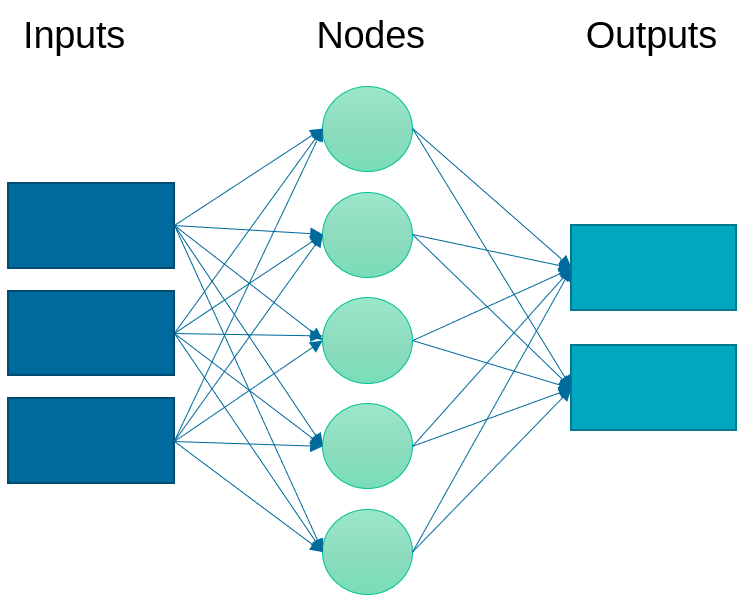

Instead of just one layer, deep learning uses a multi-layered neural network. This neural network may have linear or nonlinear layers. The layer form is determined by the type of activation function (e.g. linear, rectified linear unit (ReLU), hyperbolic tangent) that transforms each intermediate input to the next layer.

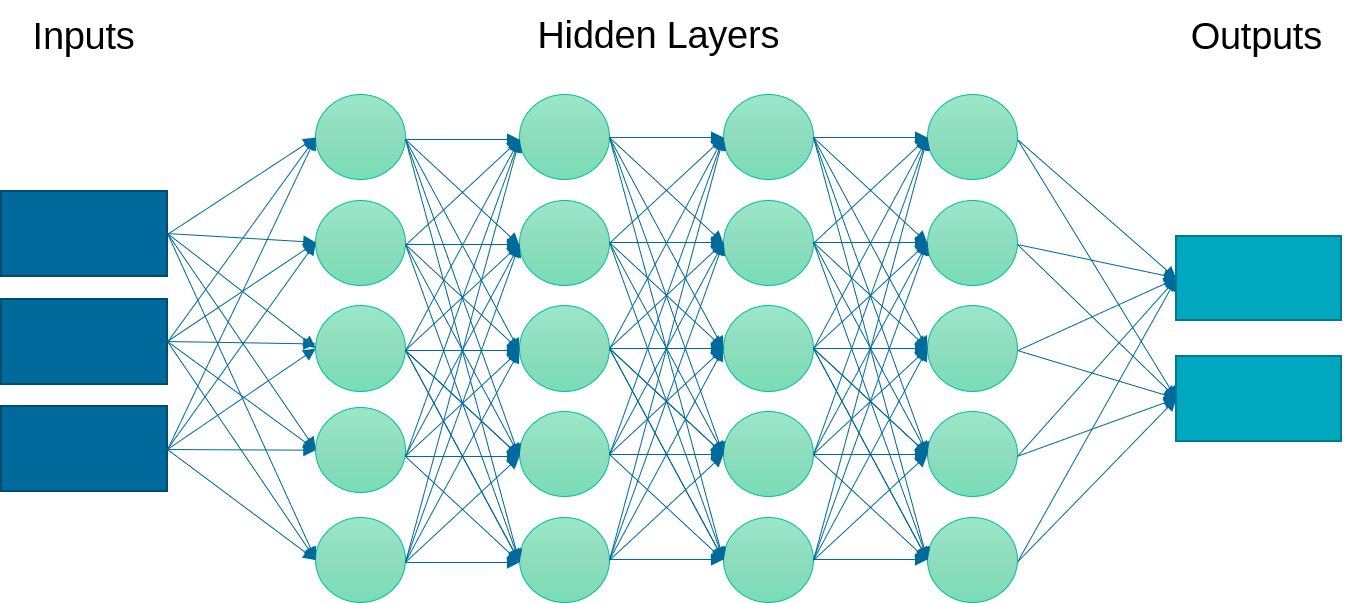

Linear layers at the beginning and end are common. Increasing the number of layers can improve the fit but also requires more computational power for training and may cause the model to be over-parameterized and decrease the predictive capability.

## Training

A loss function (objective function) is minimized by adjusting the weights (unknown parameters) of the multi-layered neural network. An epoch is a full training cycle and is one iteration of the learning algorithm. A decrease in the loss function is monitored to ensure that the number of epochs is sufficient to refine the predictions without over-fitting to data irregularities such as random fluctuations.

**3. Model Build and Train**

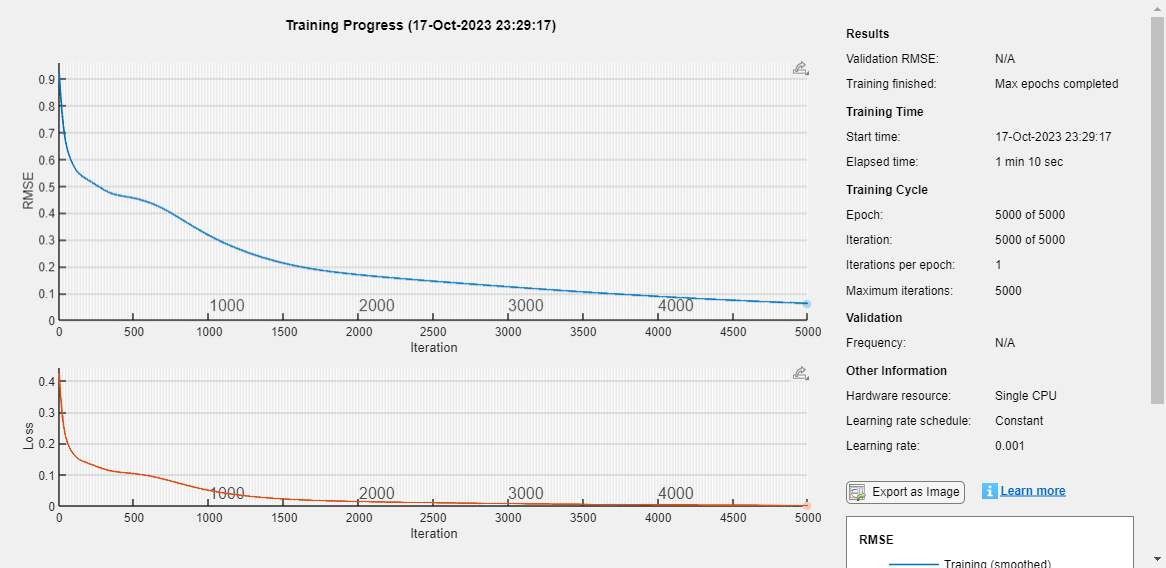

% Create layers for Neural Net
layers = [
    sequenceInputLayer(1,"Name","input")
    fullyConnectedLayer(2,"Name","fc_2")
    fullyConnectedLayer(2,"Name","fc")
    tanhLayer("Name","tanh")
    fullyConnectedLayer(2,"Name","fc_1")
    fullyConnectedLayer(1,"Name","fc_3")
    regressionLayer("Name","regressionoutput")];

% Set options for train 
options = trainingOptions("adam", ...
    MaxEpochs=5000, ...
    Verbose=false, ...
    Plots="training-progress");

% Train model to dataset 
net = trainNetwork(train_df(:,1)', train_df(:,2)', layers,options);

It's important to note that the training is processed using a compatible NVIDIA GPU if one is available, otherwise the CPU is utilized. If you would like to manually change the execution environment you can specify it in the [training options](https://www.mathworks.com/help/deeplearning/ref/trainingoptions.html). 

Note that the training process does take some time, with the following specifications it takes about a minute to process.

**Processor    **11th Gen Intel(R) Core(TM) i5-1155G7 @ 2.50GHz   2.50 GHz 

**Installed RAM    **12.0 GB (11.7 GB usable)

**System type    **64-bit operating system, x64-based processor

#### **Interactive Method**

The [Deep Network Designer](https://www.mathworks.com/help/deeplearning/deep-network-designer-app.html) app lets you build, visualize, and train deep learning networks interactively. You can import and visualize your training data, pick training options, and track the network training progress. 

## Validation

The validation test set assesses the ability of the neural network to predict based on new conditions that were not part of the training set. Parity plots are one of many graphical methods to assess the fit. Mean squared error (MSE) or the R2 value are common quantitative measures of the fit.

**4. Model Validation**

y_val = predict(net,sc_test.x');
err1 = mse(sc_test.y,y_val');
ttt = sc_test.y;
uuu=y_val;
ttmuu2 = ttt-uuu';
ccc=ttmuu2' * ttmuu2;

In this example we're finding the MSE, which is the average squared difference between the predicted values and the actual values. 

fprintf("Mean Squared Error: %.4f", err1)

Mean Squared Error: 0.0033

## Deployment

The deep learning algorithm may be deployed across a wide variety of computing infrastructure or cloud-based services. 

Self-learning algorithms continue to refine the model based on new data. This is similar to the [**Moving Horizon Estimation**](https://apmonitor.com/do/index.php/Main/EstimatorTypes) approach where unknown parameters are updated to best match the new measurement while also preserving the prior training.

% Use Model to predict beyont original model range 
x_dep = linspace(-2*pi,4*pi,100);
y_pred_dep = predict(net,x_dep); 
err_dep1 = mse(y,y_pred_dep);

tttt = y;
uuuu=y_pred_dep;
ttmuu3 = tttt-uuuu;
cccc=ttmuu3 * ttmuu3';


fprintf("Mean Squared Error: %.4f", err_dep1)

Mean Squared Error: 3.2845

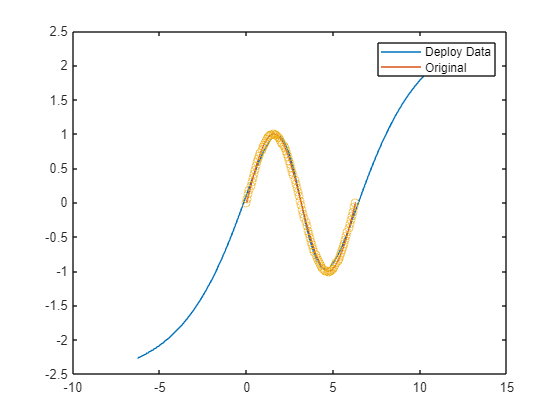


plot(x_dep,y_pred_dep)
hold on;
plot(x,y)
scatter(x, y)
hold off
legend("Deploy Data","Original")

In the above plot we can see the model predicted well within the range of the original data set, but past that data it strayed drastically from the sine function. This is why the MSE is 0.02 for the original data but jumps to 3.3 when it extrapolates past the data. 

## Activity

Repeat the above exercise that was shown but change the activation function to a cosine. By default a hyperbolic tangent function is used, but cosine will work better because of how closely it matches the sine function. With the cosine function the model will predict better when it extrapolates past the original data range. The training data is 20 equally spaced points for *x* between *0* and 2π with outputs generated from the sine function y=sin(x).

Hint: Use functionLayer to create custom cosine layer

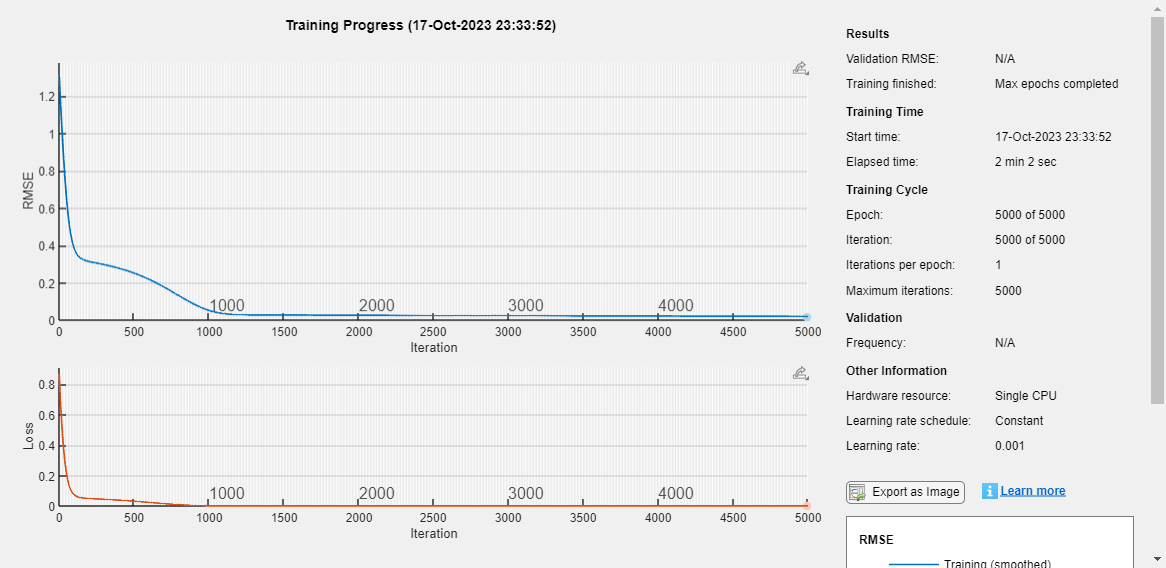

% Create cosine activation function for layer 
layer = functionLayer(@(X) cos(X));

% Remake model layers
layers_cos = [
    sequenceInputLayer(1,"Name","input")
    fullyConnectedLayer(2,"Name","fc_2")
    fullyConnectedLayer(2,"Name","fc")
    layer
    fullyConnectedLayer(2,"Name","fc_1")
    fullyConnectedLayer(1,"Name","fc_3")
    regressionLayer("Name","regressionoutput")];

% Set options for model 
options_cos = trainingOptions("adam", ...
    MaxEpochs=5000, ...
    Verbose=false, ...
    Plots="training-progress");

% Train new model on original train data
net_cos = trainNetwork(train_df(:,1)', train_df(:,2)', layers_cos,options_cos);

% Check error 
y_val_cos = predict(net_cos,sc_test.x');
tt = sc_test.y;
uu=y_val_cos;
ttmuu = tt-uu';
cc=ttmuu' * ttmuu;
err2 = mse(sc_test.y,y_val_cos');
fprintf("Mean Squared Error: %.4f", err2)

Mean Squared Error: 0.0003

% Use model to extrapolate beyond original data range
x_dep = linspace(-2*pi,4*pi,100);
y_pred_dep_cos = predict(net_cos,x_dep); 
err_dep2 = mse(y',y_pred_dep_cos');
fprintf("Mean Squared Error: %.4f", err_dep2)

Mean Squared Error: 2.7047

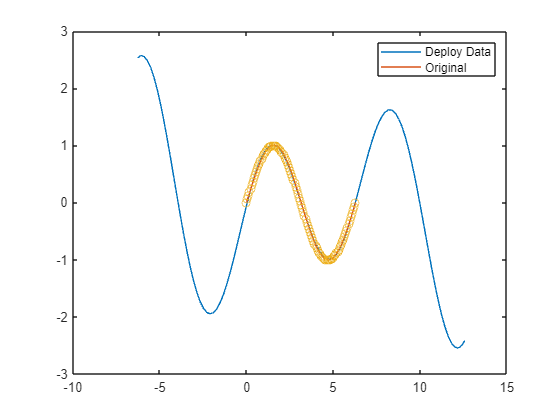


plot(x_dep,y_pred_dep_cos)
hold on;
plot(x,y)
scatter(x,y)
hold off
legend("Deploy Data","Original")

In the above plot we see that the model predicted well again for the original dataset. Past the original data set it predicted better this time than it did previously, but still strayed from the sine function. The MSE for the prediction past the data this time was 2.7 as opposed to 3.3 from the previous prediction. 

**Further Practice **

Coetsee, R., [**Deep Learning Onramp Course**](https://matlabacademy.mathworks.com/details/deep-learning-onramp/deeplearning) and [**Deep Learning with MATLAB**](https://matlabacademy.mathworks.com/details/deep-learning-with-matlab/mldl)